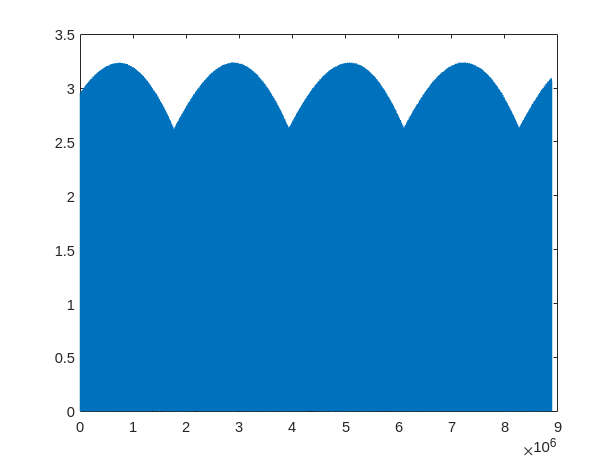

clc;clear;
% % % fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/lky.dat');
% % fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf20.dat')
% % data = fread(fid,'short');
% data = read_complex_binary('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf80_total.dat');
% load("/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/heltf80_total.mat")
% % load('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/HELTF80_tx_bb.mat');
% i = 3;
% symbollen_table = [288, 576, 1152];
% gilen_table = [32, 64, 128];

% symbollen = symbollen_table(i);
% gilen = gilen_table(i);
% 
% % time domain
% N0 = 2514;
% figure
% plot(real(data))
% hold on
% plot(imag(data))
% hold on
% % plot(imag(data(N0+1:N0+288)))
% % hold on 
% % plot(real(bb(1,:))./ 1.5)
% % hold on 
% 
% 
% figure
% corr_result = conv(data, bb(1,:));
% plot(abs(corr_result))
% hold on
% 
% figure()
% Fs = 200e6;
% t = 0:1/Fs:0.000001-1/Fs % 1000 points
% N = length(t);
% y0 = abs(fft(data(N0+1:N0+N)));
% f = (0:N-1)*Fs/N;
% plot(f,y0);
% % plot(abs(fftshift((fft(data(1:10000))))))
% hold on 
% 
% figure()
% f1 = (0:N-1)*Fs/N-Fs/2;
% y1 = abs(fftshift(fft(data(N0+1:N0+N))));
% plot(f1,y1);
% hold on
% 
% figure
% cfr_bb = fftshift(fft(transmit_bb(cfg.gilen+1:end)));
% plot(abs(cfr_bb))峰值提取
% hold on
% 
% % decode part 
% % freq shift
% % fc = 5825e6;
% % baseband_data = data.* exp(2*pi*1i*f_center*t);
% % loc_carr = exp(-1i*2*pi*(0:length(data)-1)*fc/Fs)';
% % data = data.*loc_carr;
% 
% pos = N0;
% cfr_recv = fftshift(fft(data(pos+gilen+1:pos+symbollen)))';
% plot(abs(cfr_recv))
% hold on
% % plot(real(cfr_recv))
% % hold on
% -
% cir1 = zeros(cfg.users, cfg.fftlen);
% 
% figure
% for u=1:cfg.users
% cir1(1,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
% plot(abs(cir1(1,:)))峰值提取
% hold on
% end

% % fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/lky.dat');
% fid = fopen('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf20.dat')
% data = fread(fid,'short');
% data = read_complex_binary('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/build/examples/usrp_heltf80_rx2.dat');
data = read_complex_binary('/mnt/tmp/usrp_160_CFO_1k_0_5s.dat');


load("/home/dellx/文档/uhd/host/Simulation_RU/Simulation_RU/heltf160.mat")
% load('/home/dell/下载/nju_workarea/mobile_computing/uhd/host/Simulation_RU/Simulation_RU/HELTF80_tx_bb.mat');
i = 4;
symbollen_table = [288, 576, 1152, 2304];
gilen_table = [32, 64, 128, 256];
symbollen = symbollen_table(i);
gilen = gilen_table(i);

% time domain
N0 = 3194; % 3194
figure
% plot(real(data(1:998000)))
% hold on
% plot(imag(data(1:998000)))
% hold on
% plot(abs(data(1:9980000)))
% hold on


% 
% 
% figure
% corr_result = conv(data, bb(1,1:end), 'same'); % (1:2304*N_cir)
% % plot(abs(corr_result(1:200000)))
% plot(abs(corr_result(1:2304*4)))
% hold on




data1 = [data; zeros(symbollen - mod(length(data), symbollen), 1)];
data1 = reshape(data1, [symbollen, length(data1) / symbollen]);

cfr_all=fftshift(fft(data1(cfg.gilen+1:end, :)));
cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
figure
plot(abs(cir(1:2048*4340)))
hold on

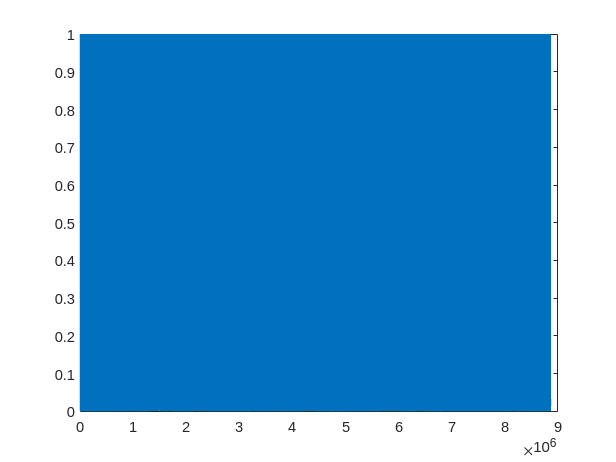

% make sure how many points changed in data
[I1,pos] = max(cir);
start = pos - pos(1) + 256+1;
finish = start + 2047;

for i =1:length(I1)
     cir(:,i)= real(cir(:, i)) / abs(I1(i)) + 1j * imag(cir(:, i)) / abs(I1(i));
%     cir(:,i)= cir(:, i) / abs(I1(i))
end
cir_imag2 = imag(cir);
cir_real2 = real(cir);
cfr=fftshift(fft(cir(:,:)));
figure
plot(abs(cir(1:2048*4330)))
hold on

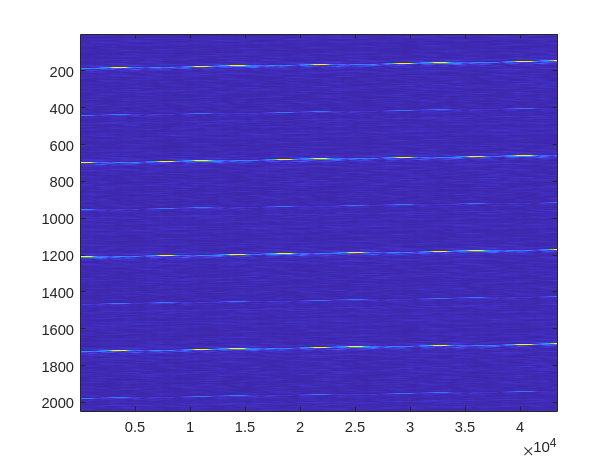

[I2,pos2] = max(cir);
% figure 
% plot(abs(I1))
% hold on
% f_I1 = fft(I1)
% figure 
% plot(abs(f_I1))
% hold on

% x = 1:1:length(I1);
% f = 994;
% % w = f*2*pi;
% % A = 0.3;
% % y = A*sin(w*t(1:10:end)) + 2.9;
% [xData,yData] = createFit1(x,abs(I1));
% 
% figure
% plot(abs(I1))
% hold on
% plot(xData,yData)
% hold on

% resample
% data_r = resample(data(1:2500000), length(data(1:2500000)) - 1, length(data(1:2500000)));
% data2 = [data_r; zeros(symbollen - mod(length(data_r), symbollen), 1)];
% data2 = reshape(data2, [symbollen, length(data2) / symbollen]);


%%%%%%%%%%%%%% chazhi %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% x = 1:1:(length(data)-40);
% xq = 1:1:length(data);
% data_real = interp1(x,real(data(1:end-40)),xq)';
% data_imag = interp1(x,imag(data(1:end-40)),xq)'; 
% data_r = data_real + 1j * data_imag;
% data2 = [data_r; zeros(symbollen - mod(length(data_r), symbollen), 1)];
% data2 = reshape(data2, [symbollen, length(data2) / symbollen]);

% 
% 
% cfr_all=fftshift(fft(data2(cfg.gilen+1:cfg.gilen+2048, :))); % cfg.gilen
% cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
% [I2,pos] = max(cir);



% figure
% plot(abs(cir(1:2048*4340)));   
% hold on
% for i = 1:length(data)
% cfr_all(:,i)=fftshift(fft(data(start(i):finish(i),i)));
% end
% cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
% figure
% plot(abs(cir(1:2048*4340)))
% hold on
% [~,pos] = max(cir);

figure
imagesc(abs(cir))
% ylim([1100, 1150])
% xlim([1 1500])data
hold on


% corr_dif = diff(corr_result2, 2, 2);
% figure
% imagesc(abs(corr_dif))
% % ylim([850, 950])
% hold on


theta = angle(cfr(:,:));
Q = unwrap(theta, 0, 2);
Q_diff = diff(Q,1,2);
% Q2 = unwrap(theta2, 0 ,2);
X = 1:length(Q) 

X =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


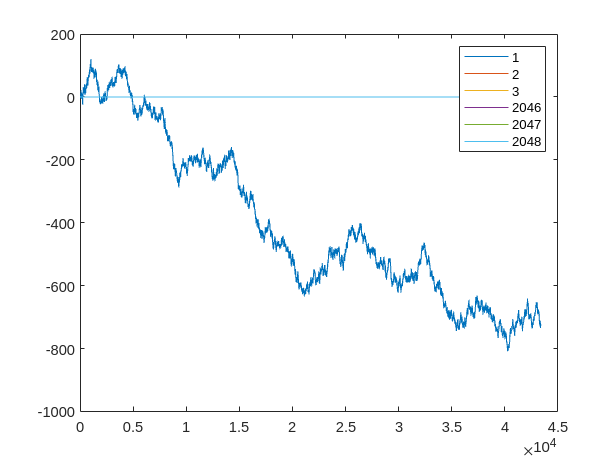

% mdl = fitlm(X, Q)
% 
% figure 
% plot(mdl)
% hold on

figure
plot(Q(1,:))
hold on
plot(Q(2,:))
hold on
plot(Q(3,:))
hold on
plot(Q(2046,:))
hold on
plot(Q(2047,:))
hold on
plot(Q(2048,:))
hold on
legend('1', '2', '3', '2046', '2047', '2048')

% 
% %  H_CFO***************************************************************
% H_CFO = exp(-1j * 0.14552 * (1:length(data)));
% cfr_all = cfr_all .* H_CFO;
% % cfr_all=fftshift(fft(data(cfg.gilen+1:end, :)));
% cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
% 
% theta = angle(cfr_all(:,:));H_CFO
% Q = unwrap(theta, 0, 2)
% figure
% plot(Q(1,:))
% hold on
% plot(Q(2,:))
% hold on
% plot(Q(3,:))
% hold on
% plot(Q(2046,:))
% hold on
% plot(Q(2047,:))
% hold onH_CFO
% plot(Q(2048,:))
% hold on   
% legend('1', '2', '3', '2046', '2047', '2048')

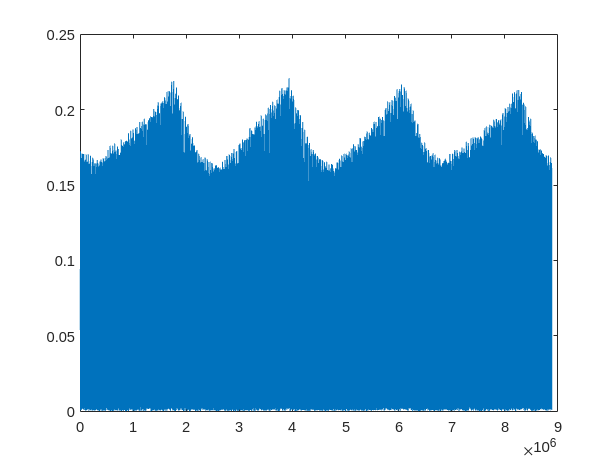

% H_SFO***************************************************************
pilot_slope_mat = mean(diff(Q));
% Calculate the SFO correction phases for each OFDM symbol
pilot_phase_sfo_corr = fftshift((-1024:1023).' * pilot_slope_mat, 1);
pilot_phase_corr = exp(-1i*(pilot_phase_sfo_corr));
% SFO_slope = exp(-1i * (0: 6305/length(cfr):6305-6305/length(cfr)));

% t = 1:1:length(cfr_all);
% H_SFO = H_SFO' * t;
cfr = cfr .* pilot_phase_corr;
cir=ifft(fftshift(cfr.*conj(cfg.userltf(1,:)'))); %convolution

figure
plot(abs(cir(1:2048*4340)))
hold on


% figure
% imagesc(abs(cir))
% % ylim([1100, 1150])
% % xlim([1 1500])data
% hold on


% *********************************************************************
% 
% theta2 = angle(cfr_all);
% Q = unwrap(theta2,0,2);
% figure
% plot(Q(1,:))
% hold on


% figure
% plot(abs(data(:,10000000)));
% hold on
% 
% 
% figure
% plot(abs(cir(1:10000000)))
% hold on

% cfo2 = cfr_all_new(1024,:) + cfr_all_new(1025,:);
% 
% theta = angle(cfo2);
% Q2 = unwrap(theta, 0, 2)
% % figure
% % plot(theta)
% % hold on
% 
% figure 
% plot(Q2)
% hold on
% 
% 
% figure
% plot(abs(cir_new(1:10000000)))
% hold on

% cfr_recv = fftshift(fft(data));
% cfr_recv = cfr_recv .* H_CFO;
% data = ifft(fftshift(cfr_recv));
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% data = data .* H_CFO;



% cfr_recv = fftshift(fft(data));
% cfr_recv = [cfr_recv; zeros(symbollen  - mod(length(data), symbollen), 1)];
% cfr_recv2 = reshape(cfr_recv, [symbollen, length(cfr_recv) / symbollen]);
% 
% cir2 = ifft(fftshift(cfr_recv2(1+gilen:symbollen, :) .* conj(cfg.userltf(1,:)')));
% figure 
% plot(abs(cir2(:,1)))
% hold on
% % plot(abs(cfr_recv))
% % hold on
% % plot(real(cfr_recv))
% % hold on
% % 
% % 
% % cir2 = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
% 


% 
% 
% 
% corr_result = [corr_result; zeros(symbollen - mod(length(corr_result), symbollen), 1)]; 
% corr_result2 = reshape(corr_result, [symbollen, length(corr_result) / symbollen]);
% 
% cfo_2 = corr_result2(1152,:) + corr_result2(1153,:);
% 
% 
% theta = angle(cfo_2);
% Q = unwrap(theta, 0, 2)
% % figure
% % plot(theta)
% % hold on
% 
% figure 
% plot(Q)
% hold on
% 
% % for i = 1:N_cir
% %     corr_result2(:, i) = circshift(corr_result2(:, i),1,1);
% % end
% 
% % buchang
% H_CFO = exp(-1j * (0.13996/2304) * (1:length(data)))';
% 
% cfr_recv = fftshift(fft(data));
% cfr_recv = cfr_recv .* H_CFO;
% data = ifft(fftshift(cfr_recv));
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % data = data .* H_CFO;
% 
% corr_result = [corr_result; zeros(symbollen - mod(length(corr_result), symbollen), 1)]; 
% corr_result2 = reshape(corr_result, [symbollen, length(corr_result) / symbollen]);
% 
% cfo_2 = corr_result2(1152,:) + corr_result2(1153,:);
% 
% t = 1:N_cir+1;
% theta = angle(cfo_2);
% Q = unwrap(theta, 0, 2)
% % figure
% % plot(theta)
% % hold on
% 
% figure 
% plot(Q)
% hold on
% 
% 
% 
% 
% tic
% figure
% corr_result3 = conv(data, bb(1,1:end), 'same'); % (1:2304*N_cir)
% % plot(abs(corr_result(1:200000)))
% plot(abs(corr_result3(1:2304*4000)))
% hold on
% toc
% 
% 
% figure
% imagesc(abs(corr_result2))
% % ylim([1100, 1150])
% % xlim([1 1500])data
% hold on
% 
% % corr_dif = diff(corr_result2, 2, 2);
% % figure
% % imagesc(abs(corr_dif))
% % % ylim([850, 950])
% % hold on
% 
% % tic
% % % rewrite corr_
% % n = length(data) + length(bb(1,:)) -1;1
% % fft_bb = fft(bb(1,:), n);
% % fft_data = fft(data, n)';t % wave_table_len
% % corr_result = ifft(fft_data .* fft_bb);
% % figure
% % plot(abs(corr_result(1:20000)))
% % hold on1
% % toc 100
% 
% % N1 = 411;
% % figure
% % plot(abs(corr_result2(N1+1,:)))
% % hold on
% % 
% % figure
% % plot(abs(corr_result2(N1+2,:)))
% % hold on
% % 
% % figure
% % plot(abs(corr_result2(N1+3,:)))
% % hold on
% % 
% % figure
% % plot(abs(corr_result2(N1+4,:)))
% % hold on

% % decode part 
% 
% row = 0;
% num = 4209
% cir2 = zeros(num+1, cfg.fftlen);
% 
% for N = N0:symbollen:N0+num*symbollen
% pos = N;
% row = row+1;
% cfr_recv = fftshift(fft(data(pos+gilen+1:pos+symbollen)))';
% 
% % plot(abs(cfr_recv))
% % hold on
% % plot(real(cfr_recv))
% % hold on
% 
% t3 = 1:12.5:12.5*1024;
% cir2(row,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
% 
% end
% 
% % % % rewrite cir2
% % data_length = num;
% % despread_data = [];
% % shaped_corr = reshape(corr_result(1:symbollen*num),symbollen,num);
% % % find the index of the max values (relative position)
% % [~,max_index] = max(abs(shaped_corr),[],1)
% % %
% % col_index = 0:symbollen:(num-1)*symbollen
% % really_index = max_index+col_index;
% % despread_data = corr_result(max_index+col_index);
% % % for loop
% % % cfr_recv = zeros(num,1024);% % rewrite cir2
% % data_length = num;
% % despread_data = [];
% % shaped_corr = reshape(corr_result(1:symbollen*num),symbollen,num);
% % % find the index of the max values (relative position)
% % [~,max_index] = max(abs(shaped_corr),[],1)
% % %
% % col_index = 0:symbollen:(num-1)*symbollen
% % really_index = max_index+col_index;
% % despread_data = corr_result(max_index+col_index);
% % % for loop
% % % cfr_recv = zeros(num,1024);
% % start_index = really_index + ones(1,num) *(gilen+1);
% % end_index = really_index + ones(1,num) * symbollen;
% % for i = 1 : num
% %     cfr_recv = fftshift(fft(data(start_index(i):end_index(i))))';
% %     cir2(i,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
% % end
% % start_index = really_index + ones(1,num) *(gilen+1);
% % end_index = really_index + ones(1,num) * symbollen;
% % for i = 1 : num
% %     cfr_recv = fftshift(fft(data(start_index(i):end_index(i))))';
% %     cir2(i,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
% % end
% 
% figure
% plot(abs(cir2(:,254)))
% hold on
% 
% figure
% plot(abs(cir2(:,255)))
% hold on
% 
% figure
% plot(abs(cir2(:,256)))
% hold on
% 
% figure
% plot(abs(cir2(:,257)))
% hold on
% 
% figure
% plot(abs(cir2(:,258)))
% hold on
% figure
% plot(abs(cir2(:,259)))
% hold on
% 
% figure
% plot(abs(cir2(:,260)))
% hold on
% 
% 
% % figure-
% % plot(abs(cir2(:,131)))% % rewrite cir2num
% % data_length = num;
% % despread_data = [];
% % shaped_corr = reshape(corr_result(1:symbollen*num),symbollen,num);
% % % find the index of the max values (relative position)
% % [~,max_index] = max(abs(shaped_corr),[],1)
% % %
% % col_index = 0:symbollen:(num-1)*symbollen
% % really_index = max_index+col_index;
% % despread_data = corr_result(max_index+col_index);
% % % for loop
% % % cfr_recv = zeros(num,1024);
% % start_index = really_index + ones(1,num) *(gilen+1);
% % end_index = really_index + ones(1,num) * symbollen;
% % for i = 1 : num1913
% %     cfr_recv = fftshift(fft(data(start_index(i):end_index(i))))';
% %     cir2(i,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
% % end
% % hold on
% % -
% % figure
% % plot(abs(cir2(:,132)))
% % hold on
% 
% figure
% for u=1:cfg.users
% cir2(1,:) = ifft(fftshift(cfr_recv.*conj(cfg.userltf(1,:))));
% plot(1:25:25*2000,abs(cir2(1,1:2000)))
% % plot(1:50:50*1024, abs(cir2(1,:)))
% hold on
% 
% end
% xlabel('Delay(ns)')
% ylabel('amplitude')
% title('CIR')
% 
